# Trabajo Grupal 2. Distribución muestral del ritmo cardiaco.

Autores: Joan Camilo Peña, Jeisson Alejandro Hernandéz, Jhon Alejandro Morales.

Abril 27 de 2024.

## Primera Actividad

Descarguen todos los archivos de la European ST-T Database (edb) en formato txt. Seguidamente, obtengan la distribución muestral de los tiempos entre picos R de toda la base de datos.

### Descarga de la base de datos

Para descargar el primer archivo se configuran los siguientes parámetros: Length: to end, Time format: elapsed time,Data format: standardyToolbox: Show RR intervals as text. Al momento de descargar el archivo se obtiene la siguiente URL:

        https://archive.physionet.org/atm/edb/e0103/atr/10/e/rr/t/rr.txt

Al realizar el mismo procedimiento para el segundo archivo se obtiene la siguiente URL:

        https://archive.physionet.org/atm/edb/e0104/atr/10/e/rr/t/rr.txt

Como se puede evidenciar al comparar las dos URL se puede identificar que lo único que varia entre ellas es el nombre del archivo, por lo cual se puede observar que la descarga de la base de datos se puede realizar mediante un código en lenguaje de programación como BASH. 

### Distribución de los datos

Para obtener una idea de como es la distribucion de los datos se procesan usando Matlab obteniendolos mediante la función leerinterval y concatenando los vectores obtenidos. Esta concatenación se pasa directamente a la función pdfcdfcontinua para estimar su función de densidad de probabilidad y su distribución acumulativa de probabilidad.

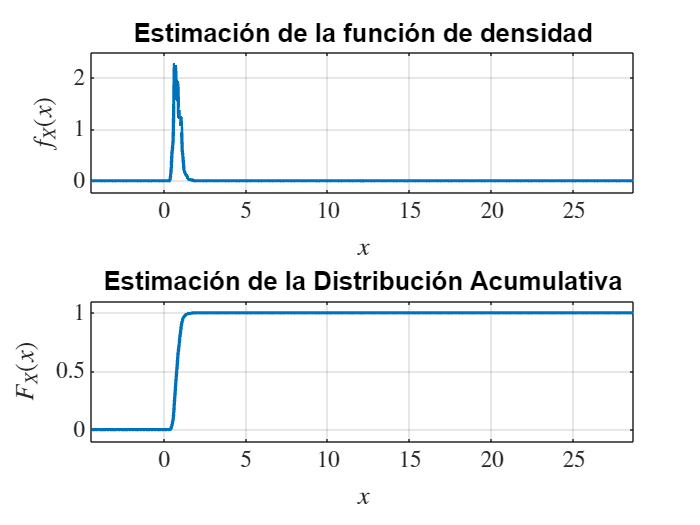

directorio='Base_de_Datos'; % carpeta donde se encuentra los archivos 
archivos_txt = dir(fullfile(directorio, '*.txt'));  %se optiene una estructura con los datos de todos los archivos txt 
intervalos_rr=[]; 
for i = 1:numel(archivos_txt) % for que recorre todo los archivos leidos
    intervalos=leerrinterval(fullfile(directorio, archivos_txt(i).name));
    intervalos_rr= [intervalos_rr ; intervalos(2:end) ]; %lectura y concatenación de los intervalos
end
clf;
pdfcdfcontinua(intervalos_rr);%estimación de la pdf  y CDF 

Al revisar la gráfica de la pdf nos damos cuenta que la mayoría de los datos se concentrarón en 0.6132 s lo que se traduce en que el valor más común para el ritmo es de 97.84 bmp. Al analizar la gráfica de la CDF nos damos cuenta que los datos de los intervalos entre picos R se encuentran con una confiabilidad del 94% entre 0.4639 s y 1.2476 s, lo que se traduce que los latidos de las personas variaron entre 48.09 bmp hasta 129.33 bmp. De acuerdo con  (*Beecardia - Physiobank - European ST-T*, s. f.) las personas tenian diagnostico o estaban en sospecha de isquemia miocárdica. Para tener en cuenta la isquemia miocárdica ocurre cuando la sangre que fluye al corazón se reduce, lo que impide que el músculo cardíaco reciba suficiente oxígeno (*Myocardial Ischemia-Myocardial Ischemia - Symptoms & Causes*, s. f.).

## Segunda Actividad

Ahora visualicen las gráficas de la pdf y la CDF para el intervalo [0,2] s. ¿Por qué razón la gráfica de la pdf aparece rellena de color? Modifiquen la función pdfcdfcontinua para que se visualice una mejor estimación de la pdf (la pdf debe mostrarse sin relleno).

### Gráficas de la pdf y CDF en el intervalo [0,2]

Se realiza la gráfica de CDF y pdf con la modificación del intervalo.

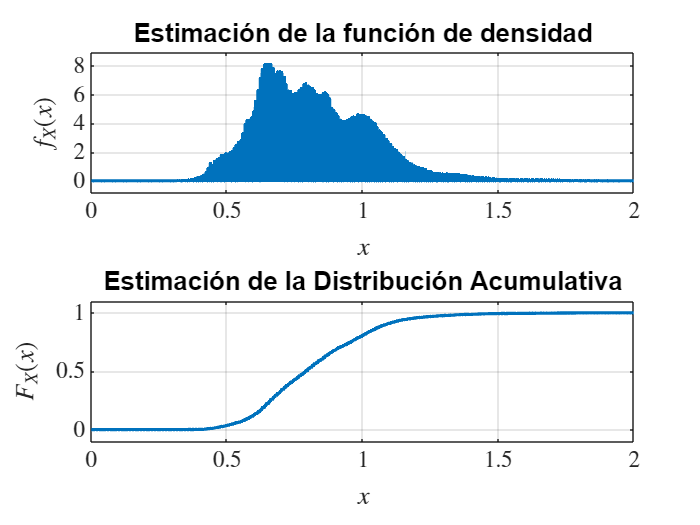

figure(7);
clf;
pdfcdfcontinua(intervalos_rr,0,2);

Al cambiar el intervalo de pdfcontinua se evidencia que la función divide la gráfica en intervalos que en algunos casos no presentan datos y la función de densidad al unir los puntos parece que estuviera rellena. Para abordar este problema se modifica la funcion pdfcdfcontinua; donde se toman las ocurrencias que lleguen a ser menores que el 10% del valor máximo alojado en ypdf y se van almacenando en arreglos, donde se guarda su valor y posición, cuando la ocurencia es identificada se entra en un bucle for que valida los siguientes cuatros datos para saber si presenta el mismo comportamiento. 

Posteriormente se calcula el valor de cada punto de la gráfica como la mediana de los valores en una ventana móvil centrada, suavizando y eliminando picos de ruido. Se ejecuta la actividad 2 con el ajuste realizado.

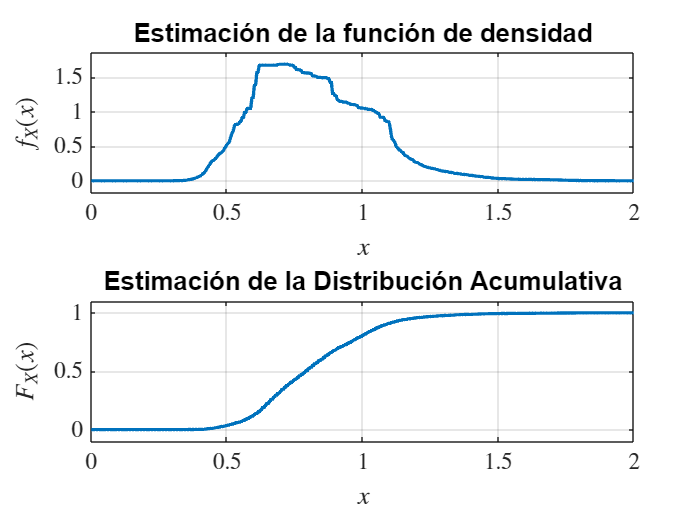

figure(8);
clf;
pdfcdfcontinua(intervalos_rr,0,2);

## Tercera Actividad

Obtengan la distribución muestral de los ritmos cardiacos instantáneos (en bpm) de toda la base de datos. Visualicen las gráficas de la pdf y la CDF para el intervalo [20,180] bpm. ¿En qué intervalo está el 95% de los ritmos cardíacos (descarten el 2,5% inicial y el 2,5% final)? ¿Qué dice la literatura especializada al respecto?

### Conversión de los datos a bmp

Para realizar la conversión de los datos en bmp se toman los intervalos entre picos RR y son dividios entre 60, correspondiendo a la cantidad de segundos en un minuto.

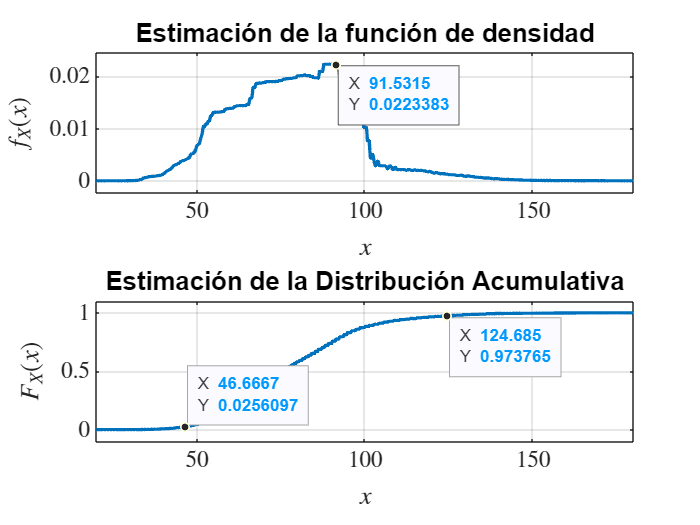

clf;
bmp=60./intervalos_rr;
bmp_filtrados=bmp((bmp >= 20) & (bmp <= 180));
pdfcdfcontinua(bmp_filtrados,20,180);

El 95% de los ritmos cardiacos obtenidos en la muestra se encuentran en el rango de 46.48 bmp a 124.6 bmp. Al revisar la función de densidad la mayor cantidad de muestras se concentra sobre 91.53 bmp. Al consultar la Sociedad Americana del corazón;  para la mayoría de los adultos, entre 60 y 100 latidos por minuto (bpm) es normal.  La tasa puede verse afectada por factores como el  **estrés, la ansiedad, las hormonas, los medicamentos y su nivel de  actividad física**. Un atleta o una persona más activa puede tener una  frecuencia cardíaca en reposo de tan solo 40 latidos por minuto(Jensen et al., 2013) .

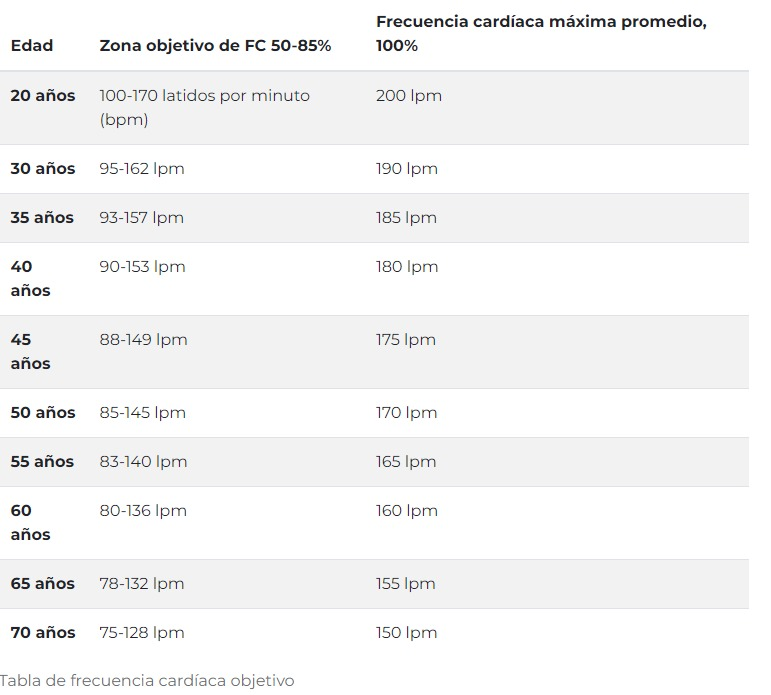

*Tabla de Frecuencia cardiaca objetivo tomado de *(American Heart Association, 2021)

De acuerdo con (*Beecardia - Physiobank - European ST-T*, s. f.) las muestras corresponden a 70 hombres de 30 a 84 años y 8 mujeres de 55 a 71 años, lo cual alude que la mayor concentración de datos sobre los 91.53 bpm, por lo tanto sus corazones están latiendo sobre los rangos de la zona objetivo que comenta la sociedad americana del corazón.

## Cuarta Actividad

Consulten otras bases de datos, además de la la European ST-T Database (edb), que contengan registros de intervalos R-R de hombres y mujeres (utilicen la herramienta PhysioBank ATM para descargar los archivos txt, correspondientes). Una vez descargados los archivos, usen la función pdfcdfcontinua para estimar las distribuciones marginales de los ritmos cardiacos (una para hombres y la otra para mujeres). Superpongan las distribuciones para compararlas. ¿Es cierto que el ritmo cardiaco de las mujeres es mayor que el de los hombres?

### Base de datos usada. 

Para esta actividad se utiliza la base de datos MIT-BIH Ritmo sinusal normal (Goldberger et al., 2000). Esta base de datos incluye 18 registros de ECG a largo plazo de sujetos  remitidos al Laboratorio de Arritmia del Hospital Beth Israel de Boston  (ahora Centro Médico Beth Israel Deaconess). Se encontró que los sujetos incluidos en esta base de datos no habían tenido arritmias  significativas; incluye 5 hombres, de 26 a 45 años, y 13 mujeres, de 20 a 50 años.

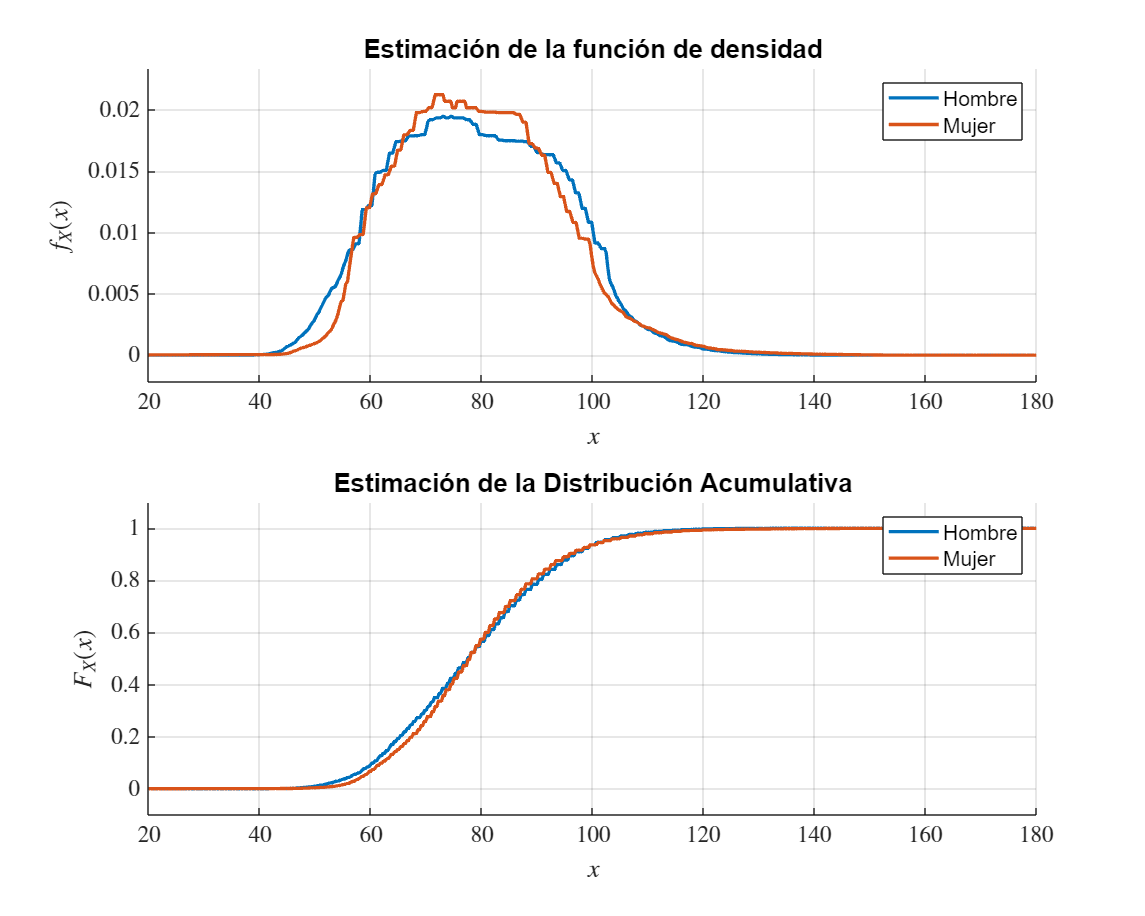

figure (1)
clf;
subplot(2,1,1)
hold on;
subplot(2,1,2)
hold on;
directorio='Base_de_Datos2\hombre'; % carpeta donde se encuentra los archivos para hombres
archivos_txt = dir(fullfile(directorio, '*.txt'));  %se optiene una estructura con los datos de todos los archivos txt 
intervalos_rr_hombre=[]; 
for i = 1:numel(archivos_txt) % for que recorre todo los archivos leidos
    intervalos=leerrinterval(fullfile(directorio, archivos_txt(i).name));
    intervalos_rr_hombre= [intervalos_rr_hombre ; intervalos(2:end) ]; %lectura y concatenación de los intervalos
end
bmp_hombre=60./intervalos_rr_hombre;
pdfcdfcontinua(bmp_hombre,20,180);%estimación de la pdf  y CDF 
directorio='Base_de_Datos2\mujer'; % carpeta donde se encuentra los archivos 
archivos_txt = dir(fullfile(directorio, '*.txt'));  %se optiene una estructura con los datos de todos los archivos txt 
intervalos_rr_mujer=[]; 
for i = 1:numel(archivos_txt) % for que recorre todo los archivos leidos para mujeres
    intervalos=leerrinterval(fullfile(directorio, archivos_txt(i).name));
    intervalos_rr_mujer= [intervalos_rr_mujer ; intervalos(2:end) ]; %lectura y concatenación de los intervalos
end
bmp_mujer=60./intervalos_rr_mujer;
pdfcdfcontinua(bmp_mujer,20,180);%estimación de la pdf  y CDF 
subplot(2,1,1)
legend('Hombre','Mujer')
subplot(2,1,2)
legend('Hombre','Mujer')
hold off
set(gcf, 'Position', [100, 100, 1000, 800]);

Desde el punto de vista electrofisiológico, las mujeres exhiben ritmos de latido más altos y una repolarización más lenta que los hombres  (Prajapati et al., 2022) . Teniendo en cuenta diferencias fisiológicas y hormonales, también es importane mencionar que los corazones de las mujeres son generalmente más pequeños en proporción a su tamaño corporal más pequeño (Legato & Leghe, 2010) y una menor cantidad de masa muscular en contraste con los hombres. A continuación se muestra la representación que es obtenida por medio de un *electrocardiograma (ECG) .*

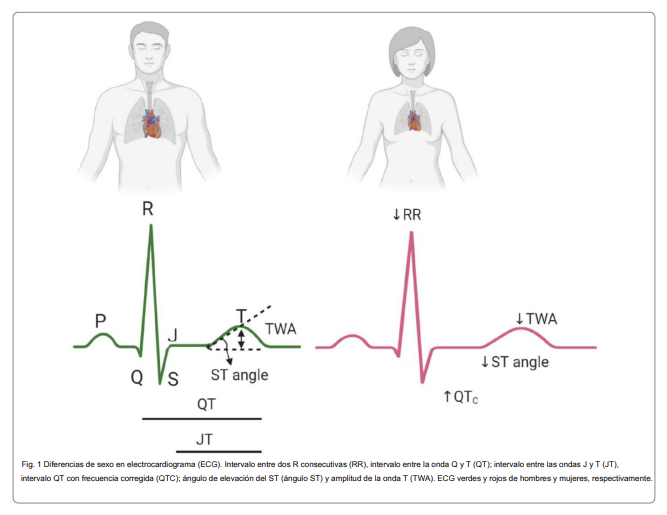

*Figura acerca de las diferencias de sexo en electrocardiogramas (ECG) tomado de *(Prajapati et al., 2022) 

- Onda T: Representa la repolarización ventricular al estado de reposo. Después de la contracción del corazón (sístole), las células cardíacas se repolarizan para prepararse para el próximo ciclo cardíaco.

- Intervalo QT: Es el período de tiempo entre el inicio del complejo QRS y el final de la onda T en el ECG. Esta medida es importante porque la duración del intervalo QT varía con la frecuencia cardíaca. Se utiliza una corrección del intervalo QT (QTC) para ajustar la duración del QT según la frecuencia cardíaca.

- Amplitud de la onda T (TWA): Se refiere al pico más alto de la onda T en el ECG. La amplitud de la onda T puede proporcionar información sobre la función eléctrica del corazón.

- Ángulo ST: Es el ángulo formado entre la línea base y los primeros 80 ms del segmento ST en el ECG. El segmento ST es la parte del ECG que sigue al complejo QRS y precede a la onda T. El ángulo ST puede ser importante para evaluar ciertos trastornos cardíacos.

- Intervalo JT: Similar al intervalo QT, se utiliza para cuantificar la duración de la repolarización. Se define como el período de tiempo del QT restado de la duración del QRS. El intervalo JT también puede ajustarse para la frecuencia cardíaca.

Estos conceptos son fundamentales en la interpretación de un ECG y en la evaluación de la actividad eléctrica del corazón en diferentes condiciones de salud y fisiológicas.

El ECG ha demostrado que las mujeres tienen frecuencias cardíacas más altas y valores absolutos más cortos del intervalo QT con una duración de ciclo más corta.

## Conclusiones

- Los intervalos RR proporcionan información directa sobre la frecuencia cardíaca, representando el tiempo entre dos latidos cardíacos consecutivos. Esto es esencial para monitorear la actividad cardíaca y detectar cualquier anormalidad en la frecuencia, ya sea una taquicardia (frecuencia cardíaca elevada) o una bradicardia (frecuencia cardíaca baja); resaltando claras asociaciones entre los valores teóricos aportados por los expecialistas y los valores bajo la experimentación y medición de pacientes.

- La identificación de eventos anormales mediante la observación de la cola de una distribución acumulativa, se puede identificar la probabilidad de eventos poco usuales o extremos. Estos eventos pueden ser importantes en diversos campos, como en la gestión de riesgos financieros (días en los que suelen haber mayor uso de tarjetas crédito o tipos de comercios que pueden recibir una mayor afluencia de clientes) o en la evaluación de desastres naturales (zonas mayormente afectadas por inundaciones).

- Las investigaciones pueden probar la o las hipótesis bajo la construcción de intervalos de confianza. Estas pruebas y intervalos permiten hacer inferencias sobre los parámetros más releantes usados en las diferentes tesis de los estudiantes de maestría, comparado sus comportamientos y entender cómo difieren en términos de tendencia central, dispersión y forma.

- Las funciones de densidad y las distribuciones acumulativas permiten modelar la incertidumbre asociada con las variables aleatorias en las redes Bayesianas. En una red Bayesiana, las distribuciones de probabilidad representan el conocimiento y la incertidumbre sobre las relaciones entre las variables, y las funciones de densidad son esenciales para describir estas distribuciones. Facilitando la interpretación de situaciones que en principio no podrían ser claramente reconocidas.

## Referencias 

*Beecardia—Physiobank—European ST-T*. (s. f.). Recuperado 21 de abril de 2024, de http://academy.beecardia.com/physiobank/database/edb

Jensen, M. T., Suadicani, P., Hein, H. O., & Gyntelberg, F. (2013). Elevated resting heart rate, physical fitness and all-cause mortality: A 16-year follow-up in the Copenhagen Male Study. *Heart*, *99*(12), 882-887. https://doi.org/10.1136/heartjnl-2012-303375

*Myocardial ischemia-Myocardial ischemia—Symptoms & causes*. (s. f.). Mayo Clinic. Recuperado 21 de abril de 2024, de https://www.mayoclinic.org/diseases-conditions/myocardial-ischemia/symptoms-causes/syc-20375417

Prajapati, C., Koivumäki, J., Pekkanen-Mattila, M., & Aalto-Setälä, K. (2022). Sex differences in heart: From basics to clinics. *European Journal of Medical Research*, *27*(1), 241. [https://doi.org/10.1186/s40001-022-00880-z](https://doi.org/10.1186/s40001-022-00880-z)

American Heart Association. (2021). *Target Heart Rates Chart | American Heart Association*. [https://www.heart.org/en/healthy-living/fitness/fitness-basics/target-heart-rates](https://www.heart.org/en/healthy-living/fitness/fitness-basics/target-heart-rates)

Goldberger, A. , Amaral, L. , Glass, L. , & Hausdorff. (2000). *Beecardia - Physiobank - MIT-BIH Normal Sinus Rhythm*. [http://academy.beecardia.com/physiobank/database/nsrdb](http://academy.beecardia.com/physiobank/database/nsrdb) 

Prajapati, C., Koivumäki, J., Pekkanen-Mattila, M., & Aalto-Setälä, K. (2022). Sex differences in heart: from basics to clinics. In *European Journal of Medical Research* (Vol. 27, Issue 1). BioMed Central Ltd. https://doi.org/10.1186/s40001-022-00880-z

Legato, M. J., & Leghe, J. K. (2010). Gender and the Heart. Sex-Specific Differences in the Normal Myocardial Anatomy and Physiology. *Principles of Gender-Specific Medicine*, 151–161. https://doi.org/10.1016/B978-0-12-374271-1.00014-9

## Anexos

A manera de revisión del ajuste realizado en la función pdfcdfcontinia se usa dicha función para evaluar una distribución uniforme, usando la función rand de Matlab y poder er el suavizado obtenido.

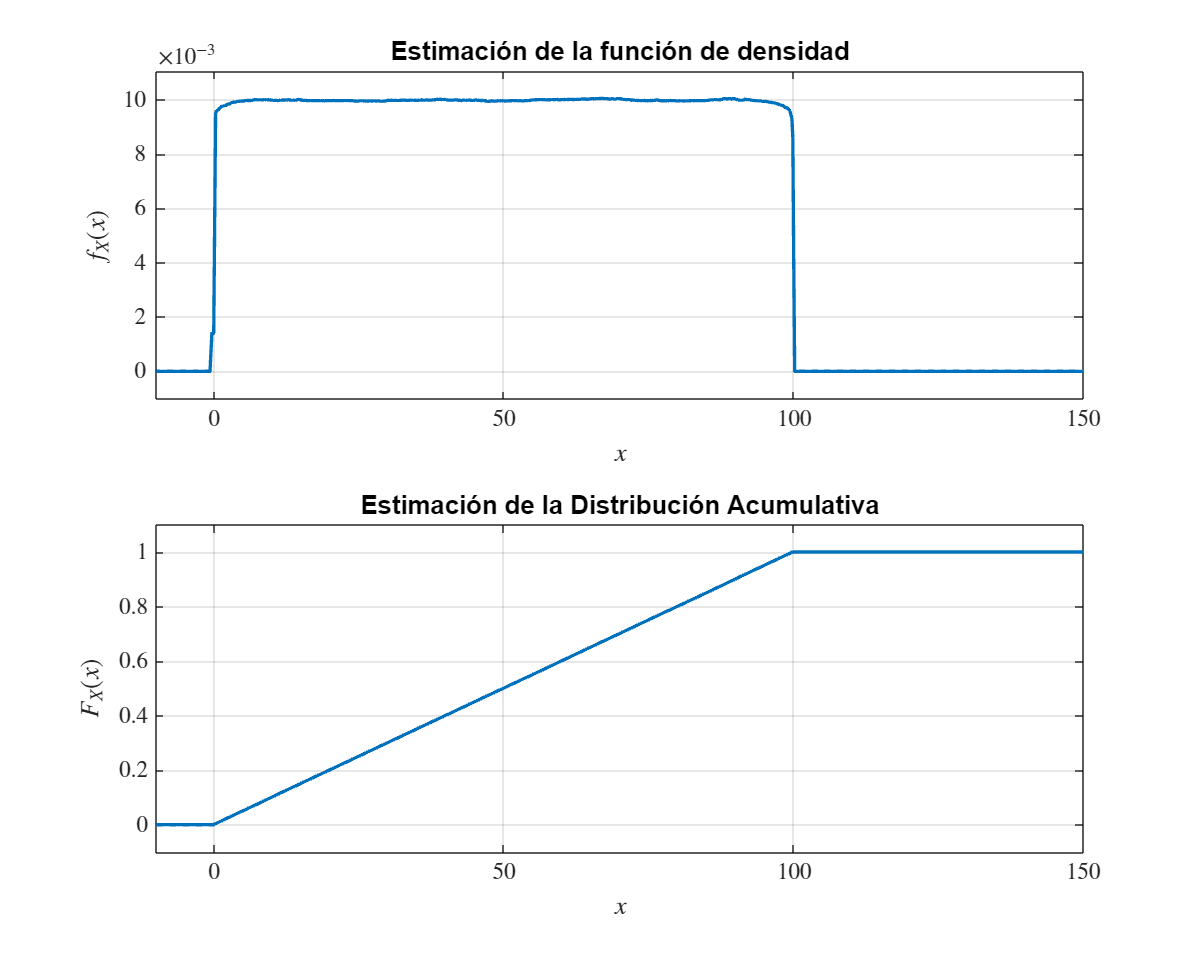

figure(2);
clf;
x=100*rand(1000);
pdfcdfcontinua(x,-10,150);